%% PHÂN TÍCH ĐA THAM SỐ: TỐI ƯU HÓA H VÀ R CHO KEYENCE FU-40S & SICK KT5W
clear; clc;

% 1. KHAI BÁO CÁC TRƯỜNG HỢP CẦN KIỂM TRA [H_mm, R_mm]
TestCases = [
    20, 30;   % TH1: H thấp, R nhỏ
    25, 35;   % TH2: H trung bình, R trung bình (Khuyến nghị)
    30, 35;   % TH3: H cao, R trung bình
    30, 60    % TH4: H cao, R lớn
];

% 2. THÔNG SỐ CỐ ĐỊNH CỦA ĐĨA VÀ CẢM BIẾN
num_segments = 6;        % LƯU Ý: Bạn đang để biến là 8 vùng (Comment ghi 4 vùng)
d0_mm = 2.2;             % Lõi sợi quang Keyence
alpha = 12 * (pi/180);   % Góc phân kỳ 12 độ (Keyence)
D_spot_sick = 2;       % Vết sáng SICK luôn cố định 1.2mm dọc
t_keyence = 300;         % Giới hạn Keyence (us)
t_sick = 50;             % Giới hạn SICK (us)
rpm_range = linspace(100, 6000, 1000); % Dải tốc độ quay

% 3. CHUẨN BỊ ĐỒ THỊ VÀ VÙNG NỀN
figure('Color', 'w', 'Name', 'Parametric Analysis: Keyence vs SICK');
hold on; grid on;

% Vẽ vùng Safe Zone và Critical Zone
fill([rpm_range, fliplr(rpm_range)], [ones(1,1000)*300, ones(1,1000)*6000], ...
    [0.8 1 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.4, 'HandleVisibility', 'off');
fill([rpm_range, fliplr(rpm_range)], [ones(1,1000)*50, ones(1,1000)*300], ...
    [1 1 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.4, 'HandleVisibility', 'off');

% 4. VÒNG LẶP TÍNH TOÁN VÀ VẼ TỪNG TRƯỜNG HỢP
colors = lines(size(TestCases, 1)); 

fprintf('--- KẾT QUẢ KIỂM TRA QUANG HỌC ---\n');

--- KẾT QUẢ KIỂM TRA QUANG HỌC ---


for i = 1:size(TestCases, 1)
    H = TestCases(i, 1);
    R = TestCases(i, 2);
    
    % --- Tính toán quang học chung ---
    S_raw = (2 * pi * R) / num_segments;
    
    % --- KEYENCE FU-40S ---
    D_spot_k = d0_mm + 2 * H * tan(alpha);
    S_eff_k = S_raw - D_spot_k;
    
    % --- SICK KT5W ---
    S_eff_s = S_raw - D_spot_sick;
    
    fprintf('TH%d [H=%d, R=%d]: S_raw = %.2f | Keyence S_eff = %.2f | SICK S_eff = %.2f\n', ...
        i, H, R, S_raw, S_eff_k, S_eff_s);
    
    % Tính toán thời gian
    r_m = R / 1000;
    v_theory = (2 * pi * rpm_range / 60) * r_m;
    
    % Vẽ Keyence (Nét liền)
    if S_eff_k > 0
        t_theory_k = ( (S_eff_k/1000) ./ v_theory ) * 1e6;
        plot(rpm_range, t_theory_k, '-', 'LineWidth', 2, 'Color', colors(i,:), ...
            'DisplayName', sprintf('Keyence (H=%d, R=%d)', H, R));
    end
    
    % Vẽ SICK (Nét đứt)
    if S_eff_s > 0
        t_theory_s = ( (S_eff_s/1000) ./ v_theory ) * 1e6;
        plot(rpm_range, t_theory_s, '--', 'LineWidth', 2, 'Color', colors(i,:), ...
            'DisplayName', sprintf('SICK (R=%d)', R));
    end
end

TH1 [H=20, R=30]: S_raw = 31.42 | Keyence S_eff = 20.71 | SICK S_eff = 29.42
TH2 [H=25, R=35]: S_raw = 36.65 | Keyence S_eff = 23.82 | SICK S_eff = 34.65
TH3 [H=30, R=35]: S_raw = 36.65 | Keyence S_eff = 21.70 | SICK S_eff = 34.65
TH4 [H=30, R=60]: S_raw = 62.83 | Keyence S_eff = 47.88 | SICK S_eff = 60.83


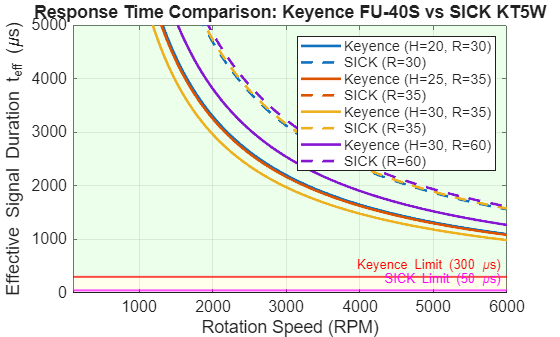


% 5. VẼ CÁC ĐƯỜNG GIỚI HẠN THIẾT BỊ
yline(t_keyence, 'r-', 'Keyence Limit (300 \mus)', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right', 'HandleVisibility', 'off');
yline(t_sick, 'm-', 'SICK Limit (50 \mus)', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'right', 'HandleVisibility', 'off');

% 6. HOÀN THIỆN ĐỒ THỊ
xlabel('Rotation Speed (RPM)');
ylabel('Effective Signal Duration t_{eff} (\mus)');
title('Response Time Comparison: Keyence FU-40S vs SICK KT5W');
legend('Location', 'northeast');
set(gca, 'FontSize', 12, 'Box', 'on');
axis([100 6000 0 5000]); 
hold off;


%% 7. XUẤT BẢNG SỐ LIỆU ĐỘNG HỌC CHO TẤT CẢ CÁC TRƯỜNG HỢP
fprintf('\n============================================================================\n');

fprintf('       BẢNG TỔNG HỢP THỜI GIAN ĐÁP ỨNG HIỆU DỤNG (UNIT: us)\n');

       BẢNG TỔNG HỢP THỜI GIAN ĐÁP ỨNG HIỆU DỤNG (UNIT: us)


fprintf('============================================================================\n');


RPM_test = [100, 200, 300, 400, 1500, 1800, 3500, 4500];

for i = 1:size(TestCases, 1)
    H = TestCases(i, 1);
    R = TestCases(i, 2);
    
    % Tính lại quang học cho từng trường hợp
    S_raw = (2 * pi * R) / num_segments;
    D_spot_k = d0_mm + 2 * H * tan(alpha);
    S_eff_k = S_raw - D_spot_k;
    S_eff_s = S_raw - D_spot_sick;
    
    fprintf('\nTRƯỜNG HỢP %d: [H = %d mm, R = %d mm]\n', i, H, R);
    fprintf('S_raw: %.2f mm | S_eff_Keyence: %.2f mm | S_eff_SICK: %.2f mm\n', S_raw, S_eff_k, S_eff_s);
    fprintf('----------------------------------------------------------------------------\n');
    fprintf('  RPM  |  V (m/s)  |  t_Keyence (us)  |  t_SICK (us)  |    Đánh giá\n');
    fprintf('----------------------------------------------------------------------------\n');
    
    % Bắt lỗi nếu gá đặt sai dẫn đến nhiễu biên hoàn toàn
    if S_eff_k <= 0
        fprintf('  [!] LỖI: Vết sáng Keyence lớn hơn cung mẫu, hệ thống bị nhiễu.\n');
        fprintf('----------------------------------------------------------------------------\n');
        continue;
    end

    for j = 1:length(RPM_test)
        rpm = RPM_test(j);
        v = (2 * pi * rpm / 60) * (R/1000);
        
        t_k = ( (S_eff_k/1000) / v ) * 1e6;
        t_s = ( (S_eff_s/1000) / v ) * 1e6;
        
        % Đánh giá theo ngưỡng thiết bị
        status = 'OK (Cả 2)';
        if t_k < t_keyence && t_s >= t_sick
            status = 'Chỉ SICK OK';
        elseif t_s < t_sick
            status = 'FAIL Cả 2';
        end
        
        fprintf(' %4d  |   %5.2f   |      %6d      |     %6d    |  %s\n', ...
            rpm, v, round(t_k), round(t_s), status);
    end
    fprintf('----------------------------------------------------------------------------\n');
end


TRƯỜNG HỢP 1: [H = 20 mm, R = 30 mm]


S_raw: 31.42 mm | S_eff_Keyence: 20.71 mm | S_eff_SICK: 29.42 mm


----------------------------------------------------------------------------


  RPM  |  V (m/s)  |  t_Keyence (us)  |  t_SICK (us)  |    Đánh giá


----------------------------------------------------------------------------


  100  |    0.31   |       65934      |      93634    |  OK (Cả 2)
  200  |    0.63   |       32967      |      46817    |  OK (Cả 2)
  300  |    0.94   |       21978      |      31211    |  OK (Cả 2)
  400  |    1.26   |       16483      |      23408    |  OK (Cả 2)
 1500  |    4.71   |        4396      |       6242    |  OK (Cả 2)
 1800  |    5.65   |        3663      |       5202    |  OK (Cả 2)
 3500  |   11.00   |        1884      |       2675    |  OK (Cả 2)
 4500  |   14.14   |        1465      |       2081    |  OK (Cả 2)


----------------------------------------------------------------------------



TRƯỜNG HỢP 2: [H = 25 mm, R = 35 mm]


S_raw: 36.65 mm | S_eff_Keyence: 23.82 mm | S_eff_SICK: 34.65 mm


----------------------------------------------------------------------------


  RPM  |  V (m/s)  |  t_Keyence (us)  |  t_SICK (us)  |    Đánh giá


----------------------------------------------------------------------------


  100  |    0.37   |       65001      |      94543    |  OK (Cả 2)
  200  |    0.73   |       32500      |      47272    |  OK (Cả 2)
  300  |    1.10   |       21667      |      31514    |  OK (Cả 2)
  400  |    1.47   |       16250      |      23636    |  OK (Cả 2)
 1500  |    5.50   |        4333      |       6303    |  OK (Cả 2)
 1800  |    6.60   |        3611      |       5252    |  OK (Cả 2)
 3500  |   12.83   |        1857      |       2701    |  OK (Cả 2)
 4500  |   16.49   |        1444      |       2101    |  OK (Cả 2)


----------------------------------------------------------------------------



TRƯỜNG HỢP 3: [H = 30 mm, R = 35 mm]


S_raw: 36.65 mm | S_eff_Keyence: 21.70 mm | S_eff_SICK: 34.65 mm


----------------------------------------------------------------------------


  RPM  |  V (m/s)  |  t_Keyence (us)  |  t_SICK (us)  |    Đánh giá


----------------------------------------------------------------------------


  100  |    0.37   |       59202      |      94543    |  OK (Cả 2)
  200  |    0.73   |       29601      |      47272    |  OK (Cả 2)
  300  |    1.10   |       19734      |      31514    |  OK (Cả 2)
  400  |    1.47   |       14800      |      23636    |  OK (Cả 2)
 1500  |    5.50   |        3947      |       6303    |  OK (Cả 2)
 1800  |    6.60   |        3289      |       5252    |  OK (Cả 2)
 3500  |   12.83   |        1691      |       2701    |  OK (Cả 2)
 4500  |   16.49   |        1316      |       2101    |  OK (Cả 2)


----------------------------------------------------------------------------



TRƯỜNG HỢP 4: [H = 30 mm, R = 60 mm]


S_raw: 62.83 mm | S_eff_Keyence: 47.88 mm | S_eff_SICK: 60.83 mm


----------------------------------------------------------------------------


  RPM  |  V (m/s)  |  t_Keyence (us)  |  t_SICK (us)  |    Đánh giá


----------------------------------------------------------------------------


  100  |    0.63   |       76201      |      96817    |  OK (Cả 2)
  200  |    1.26   |       38100      |      48408    |  OK (Cả 2)
  300  |    1.88   |       25400      |      32272    |  OK (Cả 2)
  400  |    2.51   |       19050      |      24204    |  OK (Cả 2)
 1500  |    9.42   |        5080      |       6454    |  OK (Cả 2)
 1800  |   11.31   |        4233      |       5379    |  OK (Cả 2)
 3500  |   21.99   |        2177      |       2766    |  OK (Cả 2)
 4500  |   28.27   |        1693      |       2151    |  OK (Cả 2)


----------------------------------------------------------------------------
